# Tests for debugging purposes

## The equations

## 
$$g(X,Q) = \sum_j \|X-Y_jQ_j\|^2 
\\
\nabla g(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), Y^\top(YQ-X)\bigg)
\\
\nabla^2 g(X,Q)[U,V] = \nabla g(U,V)$$


## Data and problem

n=3; % data dimension
k=5; % number of matrices
p=n; % size of factorization X of barycenter B
r=n; % size of factorization Y of data A
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

## Gradient

The slope should be 2. It appears to be: 2.
If it is far from 2, then directional derivatives might be erroneous.


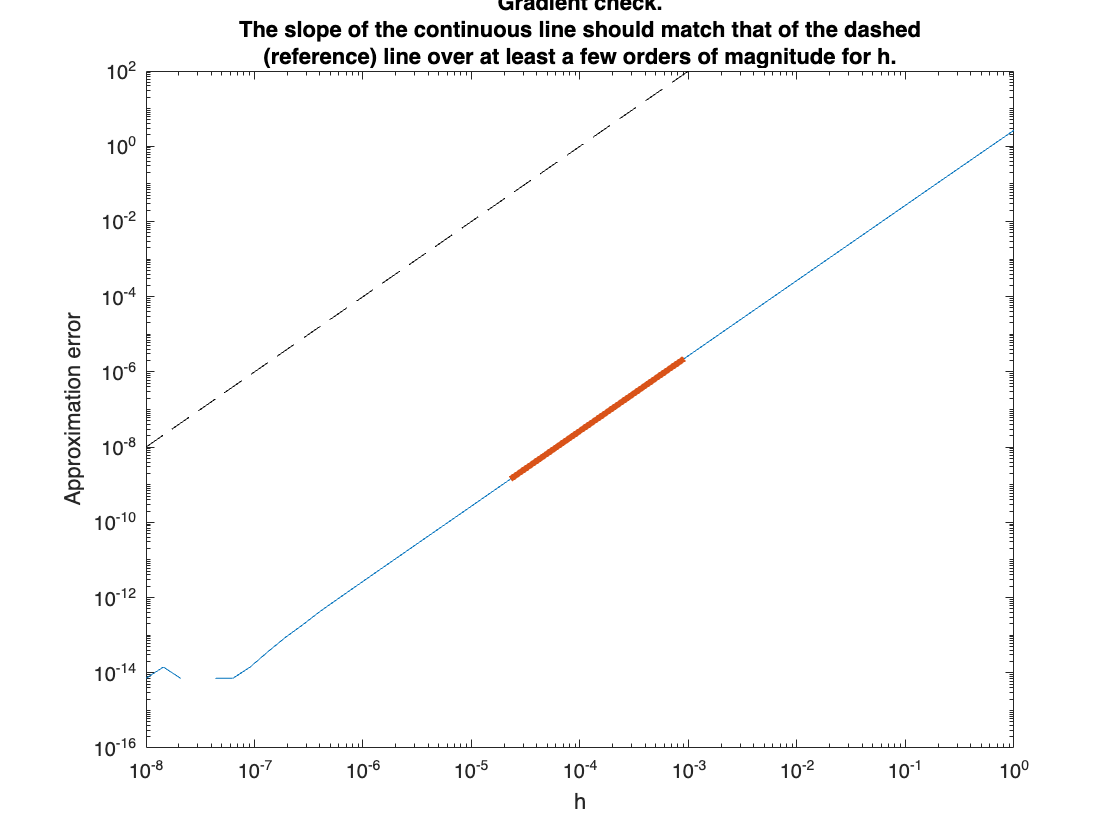

The residual should be 0, or very close. Residual: 2.7211e-15.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


checkgradient(prob);

## Hessian

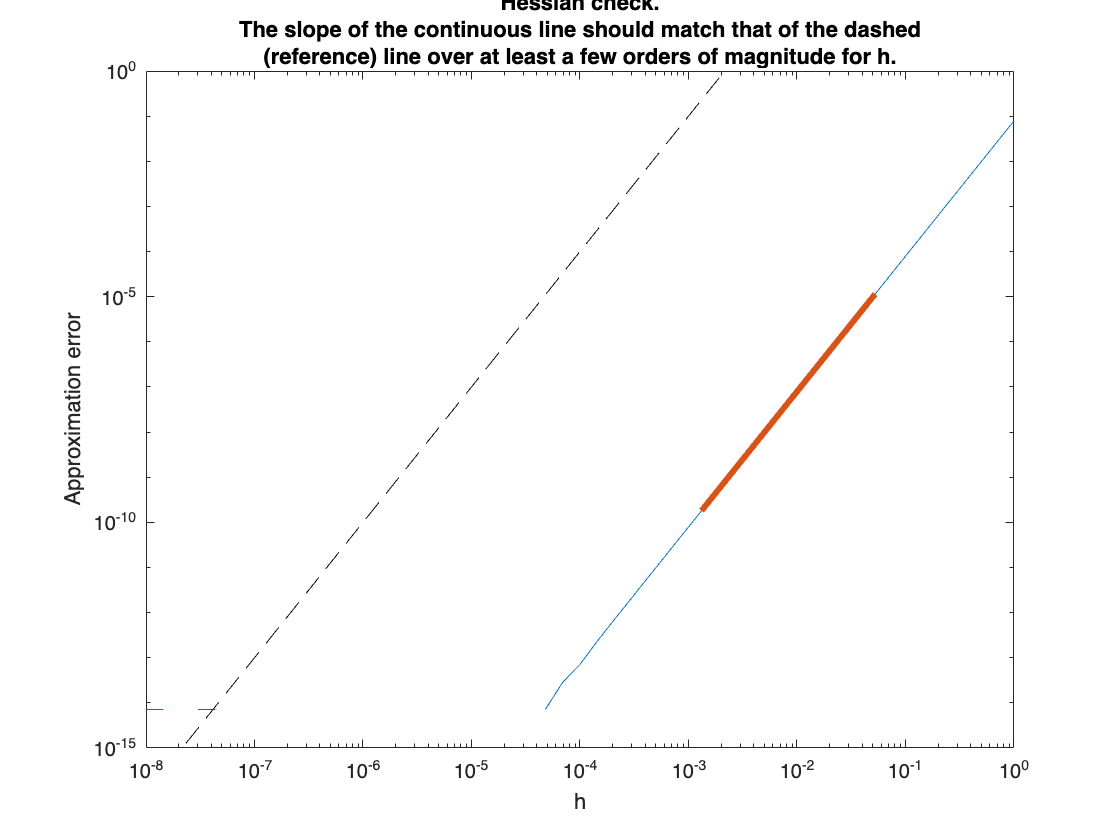

The slope should be 3. It appears to be: 3.00001.
If it is far from 3, then directional derivatives,
the gradient or the Hessian might be erroneous.
Tangency residual should be zero, or very close; residual: 1.00856e-15.
If it is far from 0, then the Hessian is not in the tangent space.
||a*H[d1] + b*H[d2] - H[a*d1+b*d2]|| should be zero, or very close.
	Value: 8.78599e-16 (norm of H[a*d1+b*d2]: 4.63521)
If it is far from 0, then the Hessian is not linear.
<d1, H[d2]> - <H[d1], d2> should be zero, or very close.
	Value: 2.06707 - 2.06707 = -4.44089e-16.
If it is far from 0, then the Hessian is not symmetric.


checkhessian(prob);

## Optimization

options.debug=1;
[x, xcost, info, options] = trustregions(prob,[],options);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   +6.3098346168597807e+01   3.142833e+01
**************************************************************************************************
DBG:     rhonum : 1.728024e+01
DBG:     rhoden : 1.728332e+01
DBG:   new f(x) : +4.581810e+01
DBG: actual rho : 9.998217e-01
DBG:   used rho : 9.998217e-01
acc TR+       1   +4.5818104976420344e+01   2.501394e+01           1           1           1   exceeded trust region
DBG: cos ang(eta, gradf): -1
**************************************************************************************************
DBG:     rhonum : 2.277123e+01
DBG:     rhoden : 2.279723e+01
DBG:   new f(x) : +2.304687e+01
DBG: actual rho : 9.988594e-01
DBG:   used rho : 9.988594e-01
acc TR+       2   +2.3046872609146433e+01   1.224657e+01           1           1           1   exceeded trust region
DBG: cos ang(eta, gradf): -1.000000e+00
************************

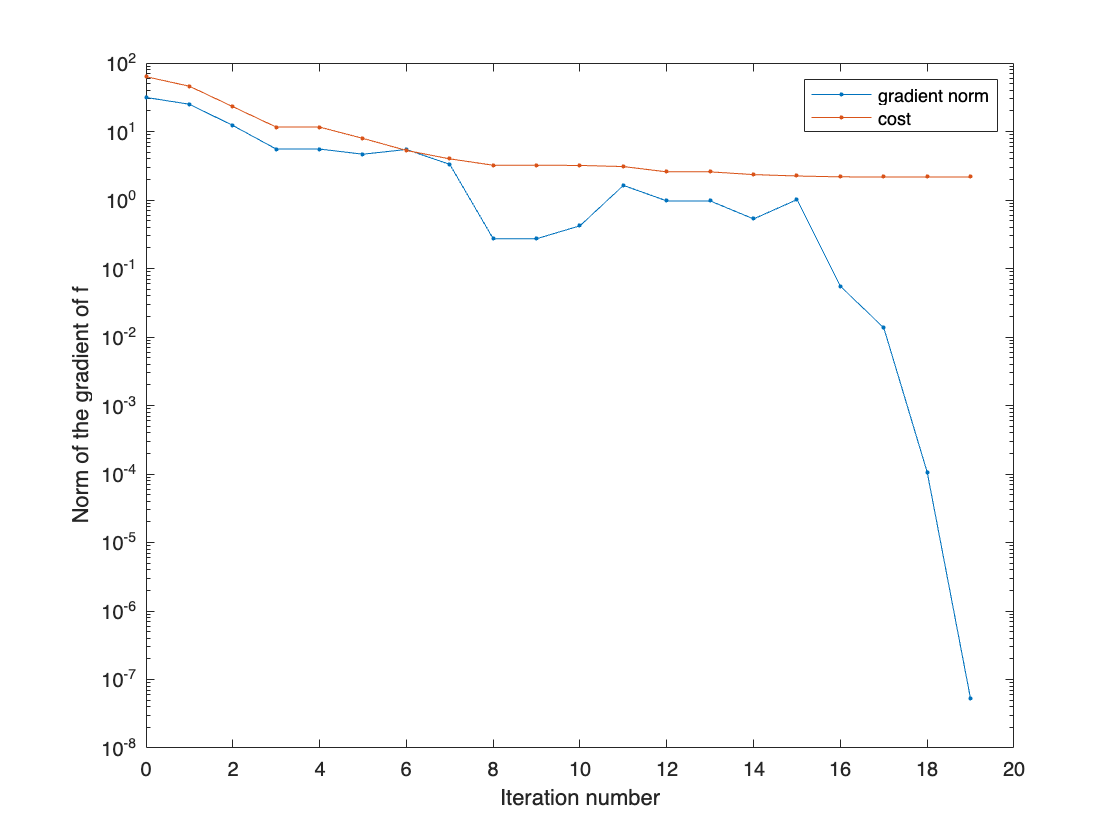

figure;
semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
xlabel('Iteration number');
ylabel('Norm of the gradient of f');
legend('gradient norm','cost')